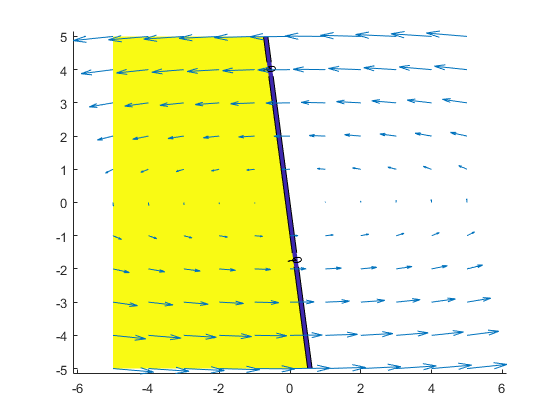

clear all
close all
A1 = [-1 -100;
    10 -1];
A2 = [1 10;
    -100 1];
E12 = [-8 -1];
E21 = [2 -1];
Q = 0.5* [E12; E21].'*[0 1; 1 0] * [E12; E21];
R12 = eye(2); R21 = eye(2);

dx1 = @(x) A1.*x; %function desribing q1
dx2 = @(x) A2.*x; %function desribing q2

%plotting settings
min = -5;
max = 5;
stepsize = 1;
figure()
%plotting everything individually to validate functionality
[X,Y,u,v] = vectorfield(A1,min,max,stepsize);
hold on

[X,Y,p] = valuefield(E12,min,max,stepsize);
contourf(X,Y,p,[0 1],'ShowText','on')

quiver(X,Y,u,v)
hold off

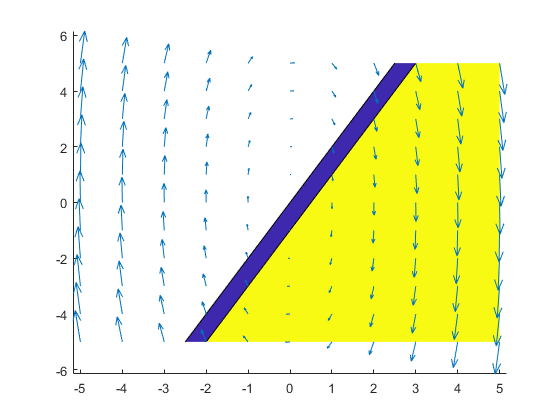


figure()
hold on
[X,Y,p] = valuefield(E21,min,max,stepsize);
contourf(X,Y,p,[0 1])

[X,Y,u,v] = vectorfield(A2,min,max,stepsize);
quiver(X,Y,u,v)



hold off

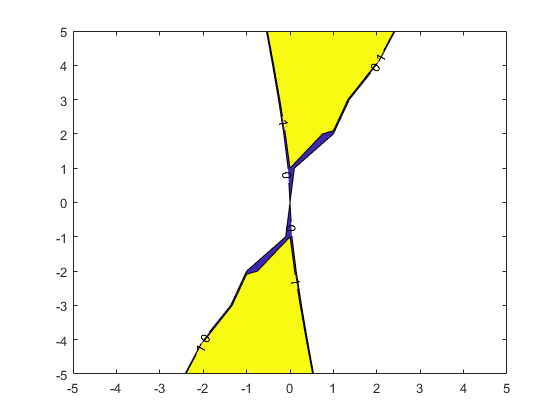


[X,Y,Qp] = Qfield(Q,min,max,stepsize);
contourf(X,Y,Qp,[0 1],'ShowText','on')

vectorsize = 0.5

vectorsize = 0.5000

mapsize = 0.01

mapsize = 0.0100


min = -5

min = -5

max = 5

max = 5

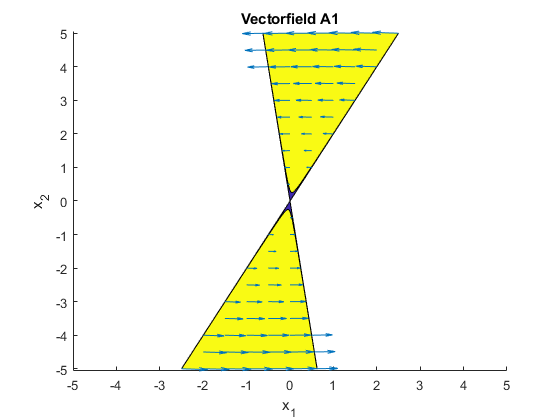


figure()
clf; hold on
%plotting the invariant map
[X,Y,Qp] = Qfield(Q,min,max,mapsize);
contourf(X,Y,Qp,[0 0.1])

%computing and plotting the vectorfield
[X,Y,u,v] = vectorfield(A1,min,max,vectorsize); %computing vectorsfield
[X,Y,Qp] = Qfield(Q,min,max,vectorsize); %recomputing feasible area to create binary map
map = zeros(length(u)); map(Qp>=0) = 1;
quiver(X,Y,u.*map,v.*map) %plotting the mapped vectorfield
title('Vectorfield A1')
xlabel('x_1'); ylabel('x_2')

hold off

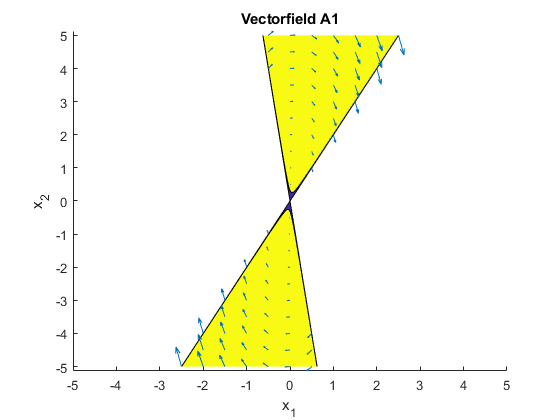


figure()
clf; hold on
%plotting the invariant map
[X,Y,Qp] = Qfield(Q,min,max,mapsize);
contourf(X,Y,Qp,[0 0.1])

%computing and plotting the vectorfield
[X,Y,u,v] = vectorfield(A2,min,max,vectorsize); %computing vectorsfield
[X,Y,Qp] = Qfield(Q,min,max,vectorsize); %recomputing feasible area to create binary map
map = zeros(length(u)); map(Qp>=0) = 1;
quiver(X,Y,u.*map,v.*map) %plotting the mapped vectorfield
title('Vectorfield A1')
xlabel('x_1'); ylabel('x_2')

hold off

figure()
x = min:stepsize:max

x =     -5    -4    -3    -2    -1     0     1     2     3     4     5


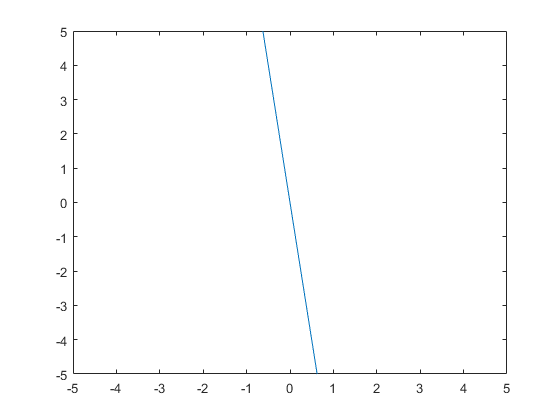

plot(x,-8*x)
ylim([-5,5]); xlim([-5,5])

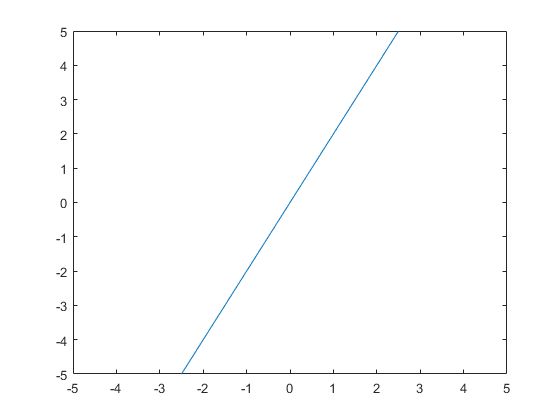


plot(x,2*x)
ylim([-5,5]); xlim([-5,5])

eig(A1)

ans =   -1.0000 +31.6228i
  -1.0000 -31.6228i


eig(A2)

ans =    1.0000 +31.6228i
   1.0000 -31.6228i


syms x y 
X = [x; y]

$$X = \left(\begin{array}{c} x\\ y \end{array}\right)$$

X.'*Q*X

$$ans = y\,\left(3\,x+y\right)-x\,\left(16\,x-3\,y\right)$$

simplify(X.'*Q*X)

$$ans = -16\,x^{2}+6\,x\,y+y^{2}$$